# ANALISI DEI DATI ACQUISITI DURANTE I TEST "MOVIMENTO A VUOTO"

In questo script si analizzano i dati acquisiti durante i test "movimento a vuoto" eseguiti il giorno 05/03/2021 presso SAMAG. Il fine è quello di descrivere il funzionamento delle principali funzioni della libreria e dimostrare l'efficacia del test.

All'inizio tutte le acquisizioni grezze vengono caricate in memoria.

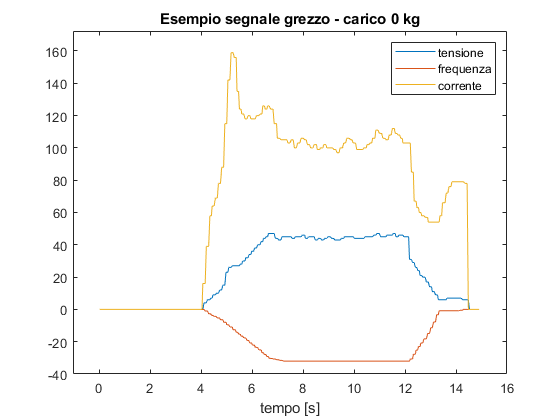

load('Test_MV_05_03_2021.mat')

% Plot di uno dei tanti segnali grezzi acquisiti dall'inverter
% (per mostrare il loro tipico andamento nel tempo)
figure
plot(MV_0kg_8s(:,1),MV_0kg_8s(:,2)) % tensione
hold on
plot(MV_0kg_8s(:,1),MV_0kg_8s(:,3)) % frequenza
plot(MV_0kg_8s(:,1),MV_0kg_8s(:,4)) % corrente
title('Esempio segnale grezzo - carico 0 kg')
xlabel('tempo [s]')
legend('tensione','frequenza','corrente')
axis padded

## Scelta del segnale nominale e ricampionamento di tutti i segnali

Una delle acquisizioni viene scelta come segnale nominale da usare come riferimento di buona salute del mezzo (il segnale di uno dei due test eseguiti con 0 kg di carico). Tutti gli altri segnali verranno confrontati con questo per determinare l'indicatore di condizione del mezzo.

Dal momento che il campionamento del segnale nominale scelto potrebbe non essere costante questo viene ricampionato alla sua frequenza di campionamento media.

Analogamente tutti gli altri segnali vengono ricampionati alla stessa frequenza di campionamento del segnale nominale per ottenere segnali confrontabili.

% Scelgo il segnale nominale e lo ricampiono ad una frequenza di campionamento 
% fissa pari alla frequenza di acquisizione media e salvo il risultato in una
% struttura dati
Sn = ricampionaSegnale(MV_0kg_8s_2(:,4), MV_0kg_8s_2(:,1),0);

% Ricampiono gli altri segnali ad una frequenza di campionamento fissa
% uguale a quella usata per il segnale nominale e salvo i risultati in
% strutture dati.
S_0kg = ricampionaSegnale(MV_0kg_8s(:,4), MV_0kg_8s(:,1),Sn.f);
S_24kg = ricampionaSegnale(MV_24kg_8s_2(:,4), MV_24kg_8s_2(:,1),Sn.f);
S_48kg = ricampionaSegnale(MV_48kg_8s_2(:,4), MV_48kg_8s_2(:,1),Sn.f);
S_72kg = ricampionaSegnale(MV_72kg_8s_2(:,4), MV_72kg_8s_2(:,1),Sn.f);

## Elaborazione del segnale nominale

Il segnale nominale ha al suo inizio e alla sua fine delle acquisizioni non significative per il test. Il segnale utile viene quindi identificato e tagliato dal resto.

Dal momento che il segnale nominale scelto è un riferimento costante i risultati dell'elaborazione vengono salvati per essere riutilizzati immediatamente in altri test senza necessità di ripetere queste operazioni.

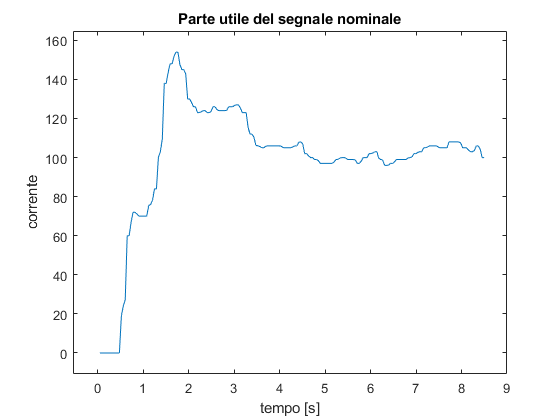

n_d = 8; % [2,8] ordine del filtro FIR usato per calcolare la derivata prima
inizio_soglia = 0.7; % (0,1] soglia come moltiplicatore per determinare l'inizio del segnale utile
durata = 8; % [s] durata del test
margine_inizio = 0.5; % [s] margine di tempo aggiunto all'inizio del segnale utile identificato

Sn_t = tagliaSegnaleUtile_mv(Sn,n_d,inizio_soglia,durata,margine_inizio);

% Plot del segnale utile identificato e ritagliato
figure
plotSegnale(Sn_t);
title('Parte utile del segnale nominale')
ylabel('corrente')
axis padded


% Il pratica questo segnale verrà salvato per poter essere riutilizzato
% quando serve senza bisogno di ripetere le elaborazioni
% "save(Sn_t);"

## Elaborazione dei segnali acquisiti

I segnali acquisiti hanno al loro inizio e alla loro fine delle acquisizioni non significative per il test.  La parte utile dei segnali viene quindi identificata e tagliata dal resto.

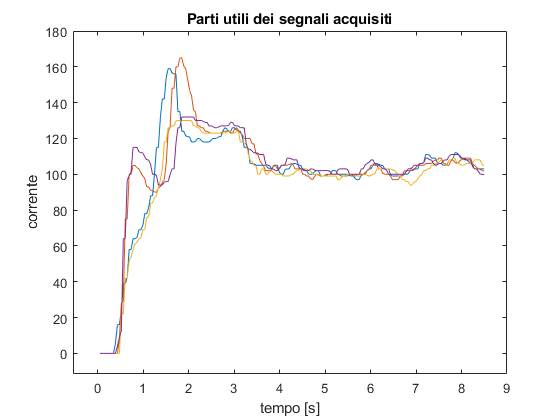

% Parametri per elaborazione dei segnali acquisiti
n_d = 8; % [2,8] ordine del filtro FIR usato per calcolare la derivata prima
inizio_soglia = 0.7; % (0,1] soglia come moltiplicatore per determinare l'inizio del segnale utile
durata = 8; % [s] durata del test
margine_inizio = 0.5; % [s] margine di tempo aggiunto all'inizio del segnale utile identificato

S_0kg_t = tagliaSegnaleUtile_mv(S_0kg,n_d,inizio_soglia,durata,margine_inizio);
S_24kg_t = tagliaSegnaleUtile_mv(S_24kg,n_d,inizio_soglia,durata,margine_inizio);
S_48kg_t = tagliaSegnaleUtile_mv(S_48kg,n_d,inizio_soglia,durata,margine_inizio);
S_72kg_t = tagliaSegnaleUtile_mv(S_72kg,n_d,inizio_soglia,durata,margine_inizio);

% Plot dei segnali utili identificati e ritagliati
figure
plotSegnale(S_0kg_t);
hold on
plotSegnale(S_24kg_t);
plotSegnale(S_48kg_t);
plotSegnale(S_72kg_t);
title('Parti utili dei segnali acquisiti')
ylabel('corrente')
axis padded

## Calcolo indice "Minimo Errore Quadratico Medio"

Viene calcolato un indicatore di somiglianza tra il segnale nominale e i segnali acquisitoi Tale indicatore determina lo stato di salute del mezzo e la sua idoneità ad essere utilizzato.

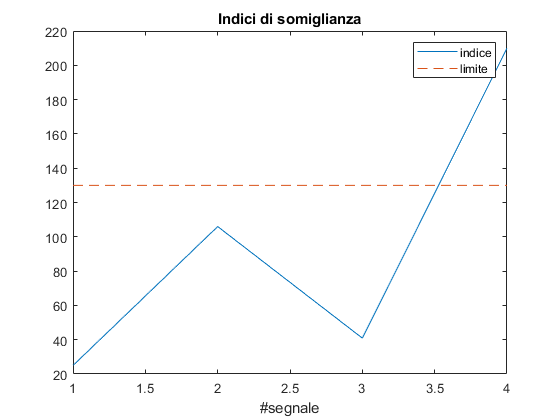

% Calcolo dell'indice di correlazione tra il segnale nominale e ciascuno dei 
% segnali acquisiti. Minore è l'indice maggiore è la somiglianza tra i due segnali.
ind_0kg = Ind_minErroreQuadraticoMedio_sv(Sn_t,S_0kg_t);
ind_24kg = Ind_minErroreQuadraticoMedio_sv(Sn_t,S_24kg_t);
ind_48kg = Ind_minErroreQuadraticoMedio_sv(Sn_t,S_48kg_t);
ind_72kg = Ind_minErroreQuadraticoMedio_sv(Sn_t,S_72kg_t);

% In base a una soglia si determina se il mezzo su cui è eseguito il test è
% idoneo ad essere utilizzato
ind_lim = 130;

% Plot degli indici di somiglianza calcolati e del limite imposto
figure
Y_plot_temp = [ind_0kg ind_24kg ind_48kg ind_72kg];
plot(Y_plot_temp)
hold on
plot(ones(1,length(Y_plot_temp))*ind_lim,'--')
title('Indici di somiglianza')
xlabel('#segnale')
legend('indice','limite')